# Elaborato equazioni differenziali ordinarie.

## Modello SIR di diffusione di un'epidemia

Di seguito si risolve il sistema di equazioni differenziali, definite nel file *SIR.m. *Le soluzioni sono ottenute considerando diversi valori del paramentro `a`. Si dimostra, tramite i grafici, come le soluzioni delle equazioni variano sostanzialmente al variare del parametro `a`. Inoltre viene calcolato il picco dell'epidemia ovvero la coppia di valori `(x,y)` per cui il numero di persone infette è massimo.

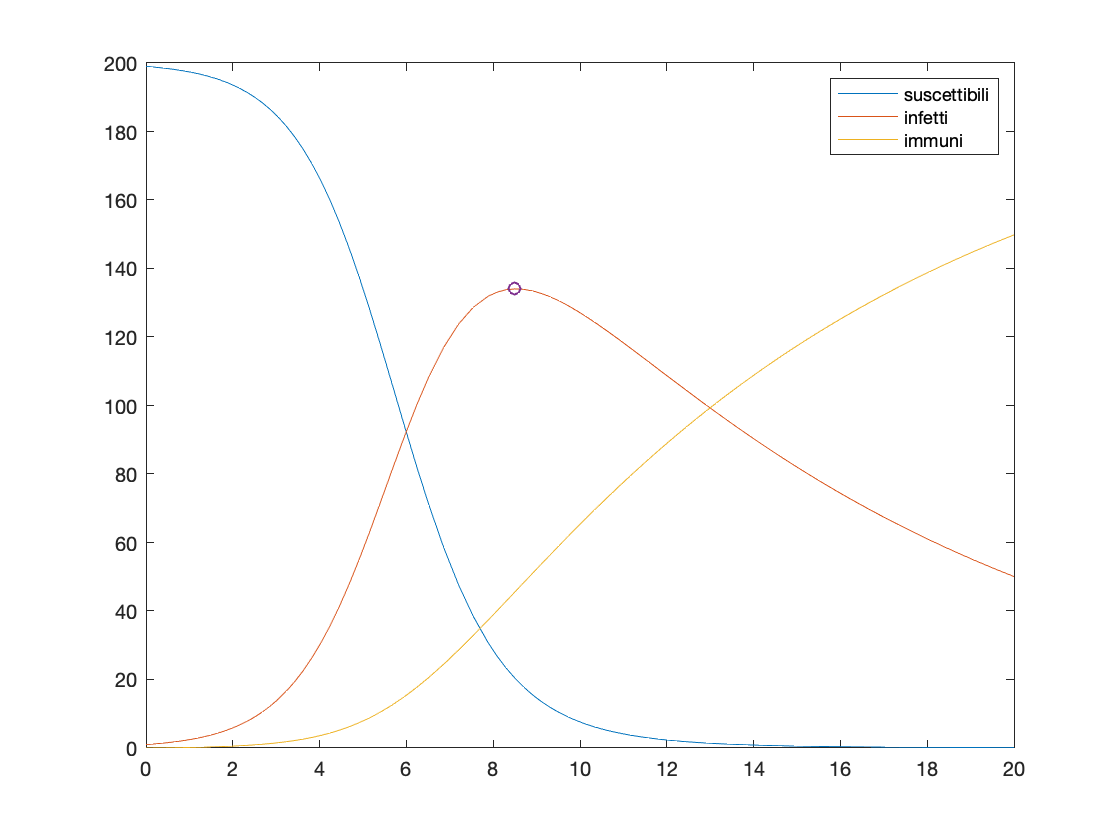

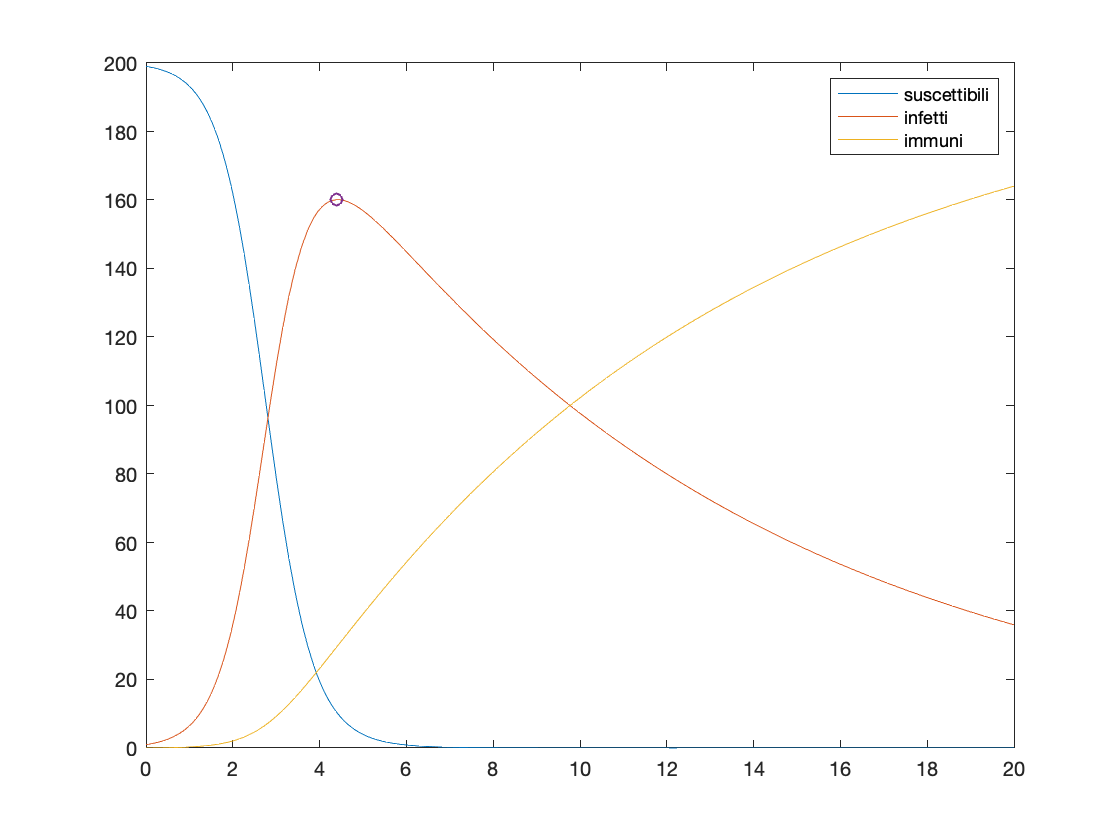

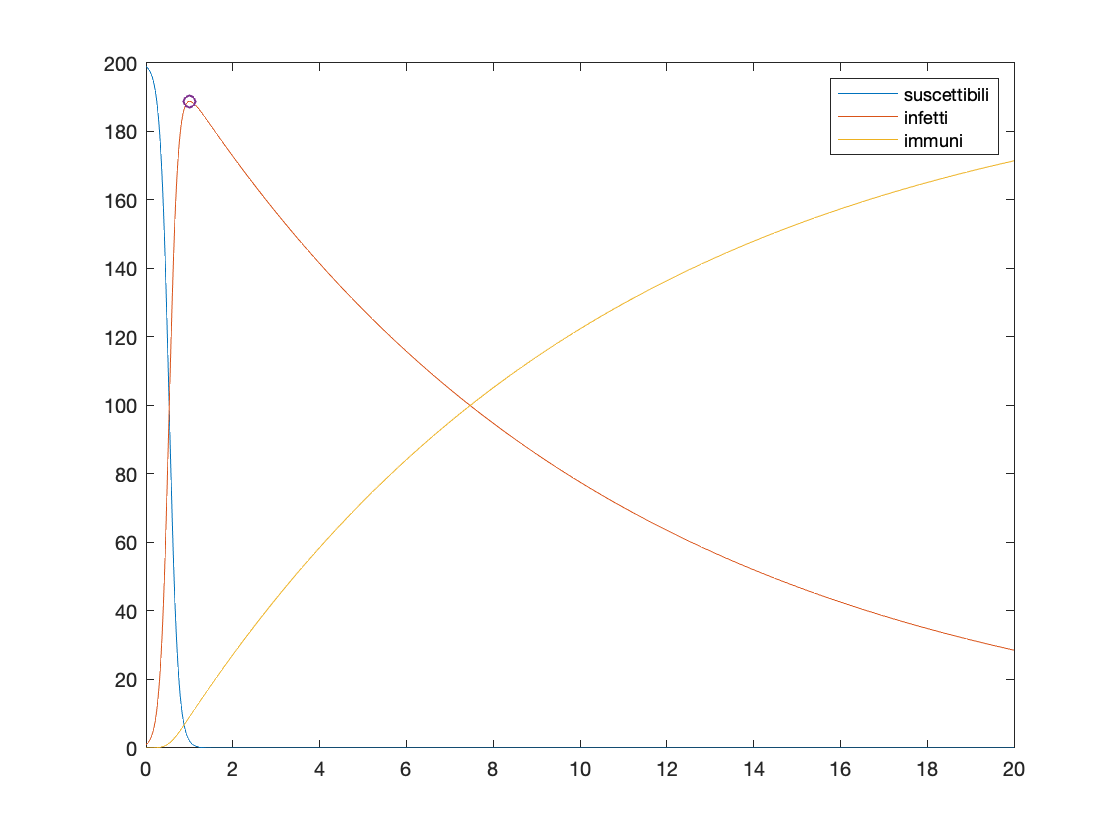

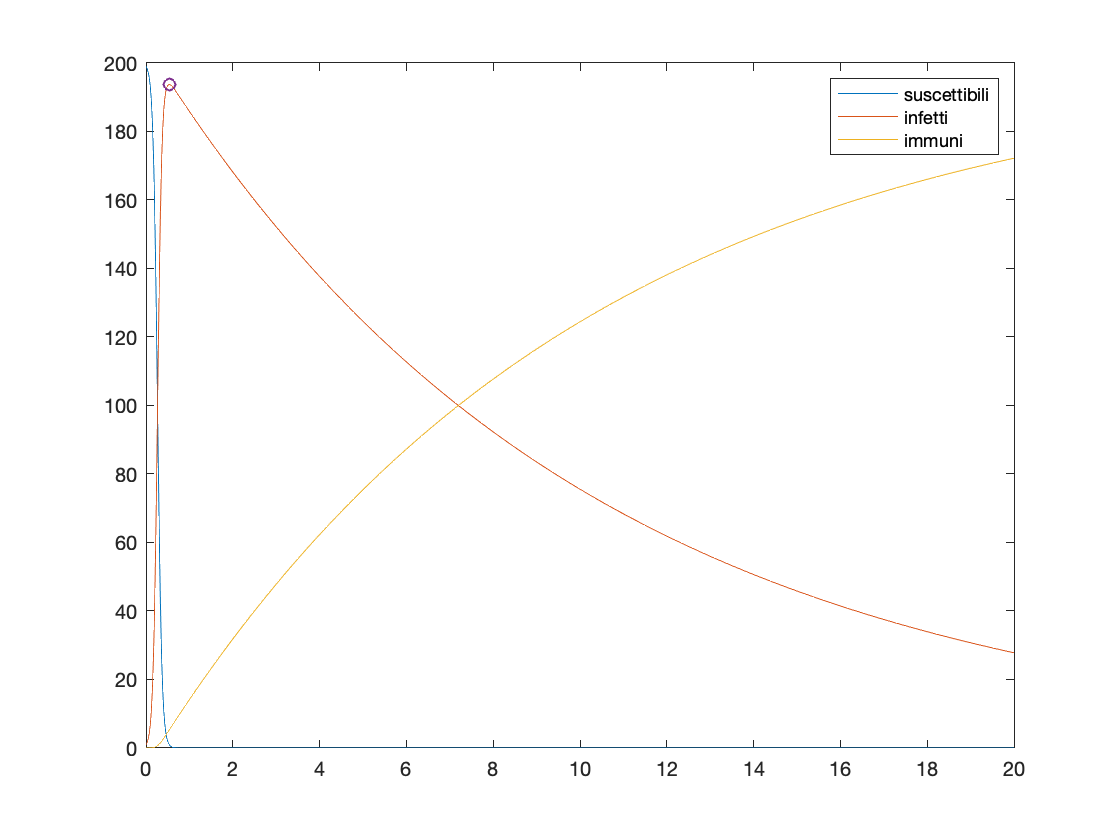

y0 = [199;1;0];
opt=odeset('RelTol',1e-4);
a = [0.005;0.01;0.05;0.1];

for i = 1:length(a)
    [t, x] = ode45(@SIR,[0 20],y0,opt,a(i));
    picco=max(x(:,2));
    tpicco=t(x(:,2)==picco);
    figure('Name',['ode con a = ' num2str(a(i),5),'.']);
    plot(t,x(:,1),t,x(:,2),t,x(:,3),tpicco, picco, "o"); legend("suscettibili", "infetti" , "immuni");
end

## Sistema stiff

Nella seguente sezione si risolve il sistema di equazioni differenziali definite nel file* oregonator.m. *Le soluzioni sono ottenute dapprima mediante la funzione Matlab `ode45`, quindi mediante la funzione `ode15s`, appositamente dedicata alla risoluzione di problemi stiff. Si nota come `ode15s` effettui un numero di valutazioni di funzione molto inferiore rispetto a `ode45`, riducendo notevolmente complessità e tempi di calcolo. 

y0 = [0.2;0.2;0.2];
opt=odeset('RelTol',1e-6,'AbsTol',1e-7);
argin = [9e-5, 1e-2, 2.5e-5, 0.8];

[t, x] = ode45(@oregonator,[0 50],y0,opt,argin);
f = @()ode45(@oregonator,[0,50],y0,opt,argin);
timeit(f)

ans = 24.5387

ode45_length = length(t)

ode45_length = 1402465

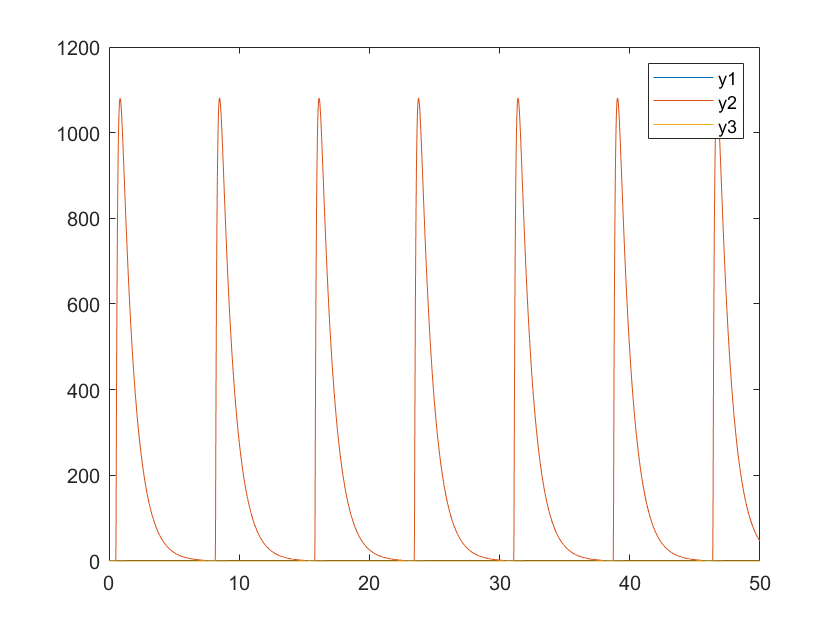

figure('Name','Risoluzione con ode45.');
plot(t,x(:,1),t,x(:,2),t,x(:,3)); legend("y1", "y2" , "y3");

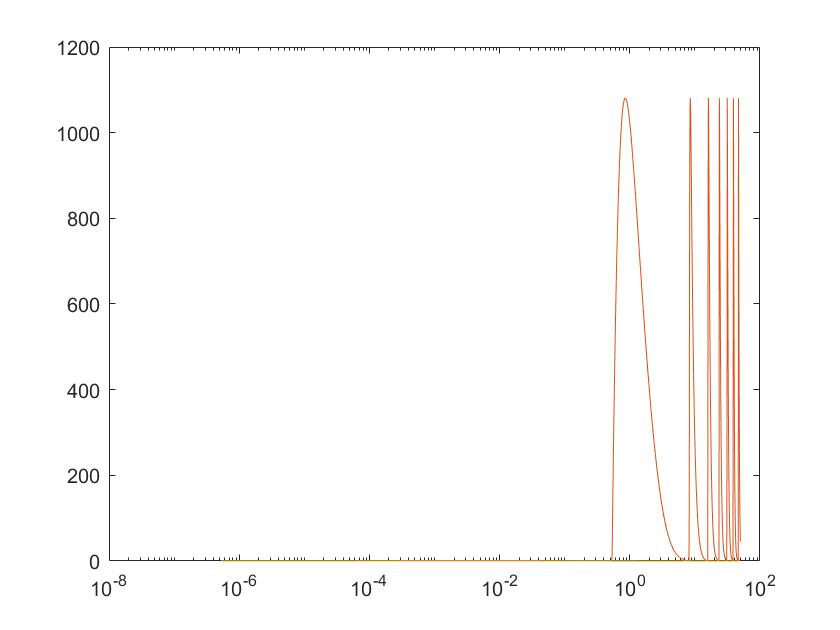

figure('Name','ode45: semilog');
semilogx(t,x);


[t1, x1] = ode15s(@oregonator,[0 50],y0,opt,argin);
f1 = @()ode15s(@oregonator,[0,50],y0,opt,argin);
timeit(f1)

ans = 0.6371

ode15s_length = length(t1)

ode15s_length = 3668

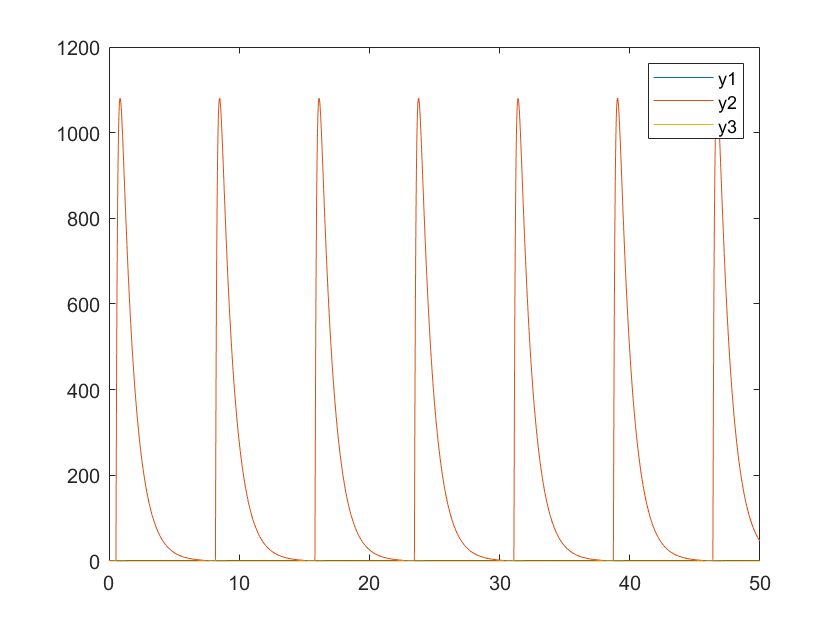

figure('Name','Risoluzione con ode15s.');
plot(t1,x1(:,1),t1,x1(:,2),t1,x1(:,3)); legend("y1", "y2" , "y3");

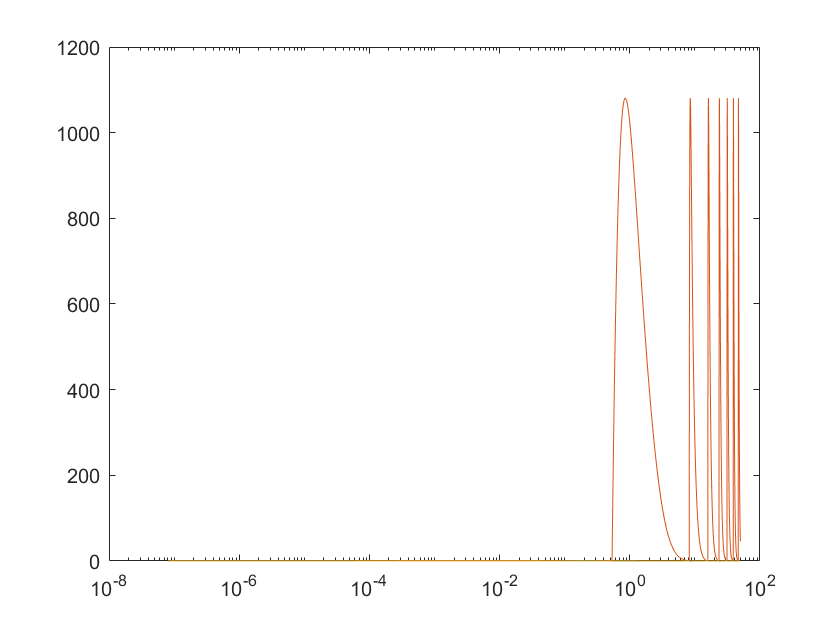

figure('Name','ode15s: semilog');
semilogx(t1,x1);